# 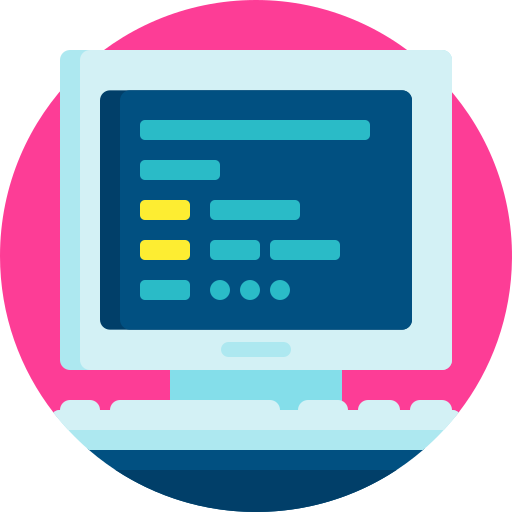

# Virtual Lab 8: Design specifications

**This Virtual Lab covers content in Chapter 11 of the course notes**

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on Right`.

- This script has been sectioned off — you can use `Run Section `(CMD/CNTL+ENTER) instead of` Run `when in a particular section. This will only evaluate code in the section. 

- This virtual lab requires the following `MATLAB` toolboxes: Control Systems Toolbox, Symbolic Math Toolbox.

- You can use the `help` function to get information on a function within the `MATLAB Command Window`, e.g. `help laplace`.

## Sensitivity in the frequency domain

### Design objective

As previously introduced, the sensitivity function is given by

$S(s)=\frac{1}{1+P(s)G(s)}=\frac{1}{1+L(s)}$,

where $L(s)=P(s)G(s)$ is the loop transfer function for a system in unity-feedback as shown in the block diagram below. 

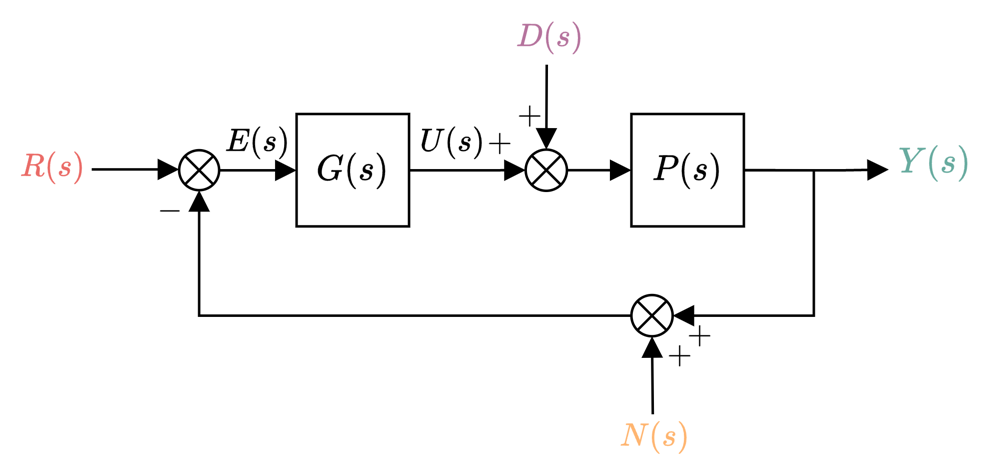

With reference to the block diagram, the tracking error is given by

$E(s) = \frac{1}{1+P(s)G(s)}R(s)-\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{1}{1+P(s)G(s)}N(s)$,

where $N(s)$ is zero-mean high-frequency noise, and $D(s)$ is a load disturbance. Based on the equation above, the sensitivity function also represents the transfer behaviour from the reference signal and noise to the tracking error, and is directly proportional to the transfer behaviour from the disturbance to error. In other words, the equation above can be parameterised by the sensitivity function as

$E(s) = S(s)R(s)-PS(s)D(s)-S(s)N(s)$.

If our objective is for the output response $Y(s)$ to match the reference $R(s)$ in some manner, then we are equivalently attempting to make $E(s)=R(s)-Y(s)$ sufficiently small at low frequencies (when $n(t)\approx 0$), as this will make $e(t)=r(t)-y(t)$ small. Based on the equation above, we can do this by making the sensitivity function sufficiently small ($|S(j\omega)|\ll 1$)  at frequencies where we expect $R(s)$ and $D(s)$ to act — usually at low frequencies — so that all expected reference signals can be approximately tracked. Owing to the fact that there will be sensor noise at higher frequencies via $N(s)$, we then make $|S(j\omega)|\approx 1$ for all other frequencies.

Our only means of adjusting the sensitivity function is to adjust $G(s)$, so it would be useful to have a clear picture of how $G(s)$ affects $S(s)$ across all frequencies. 

### Relationship with stability margin

Recall that the stability margin, $s_M$, is defined as the distance between the critical point and the *closest* point of $L(j\omega)$ when visualised in a Nyquist diagram, as shown below. 

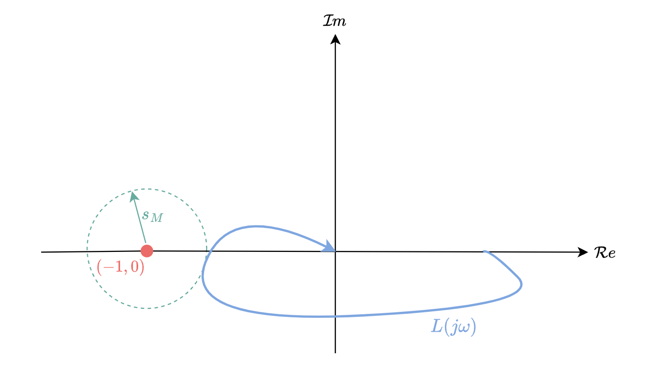

Mathematically, this can be written as

$
s_M 
\leq |1+L(j\omega)|
$,

Which implies that the distance between any point on $L(j\omega)$ and the critical point is always equal to or greater than $s_M$. The stability margin is related to the gain and phase margins in that it gives us an indication of closed-loop stability based on how far away $L(j\omega)$ is from the critical point. If we divide both sides of the equation above by $s_M|1+L(j\omega)|$, we get

$\left| \frac{1}{1+L(j\omega)}\right| \leq \frac{1}{s_M}$,

where the left-hand side of the above equation is now the magnitude response of the sensitivity function, and the right-hand side is the inverse of the stability margin. Making the sensitivity function small at all frequencies will therefore ensure that the stability margin is large based on the relationship above. This means that our objectives to track reference signals and have good stability margins are aligned — both require small sensitivity functions. However, for the purposes of a good stability margin, we only need to make $|S(j\omega)|$ small when in the vicinity of the critical point.

The mathematical relationship above also implies that the maximum value of $\left| S(j\omega)\right|=\left| \frac{1}{1+L(j\omega)}\right| $ will be equal to $\frac{1}{s_M$, namely

 $\left| S(j\omega)\right|_{max}=\frac{1}{s_M}$,

which we can read off from a Bode magnitude response graph of $|S(j\omega)|$ in order to design for or analyse the stabiity margin.

#### Example

*Determine the stability margin from the Bode magnitude response of the sensitivity function when *$L(s)=\frac{5}{s(s+1)}$.

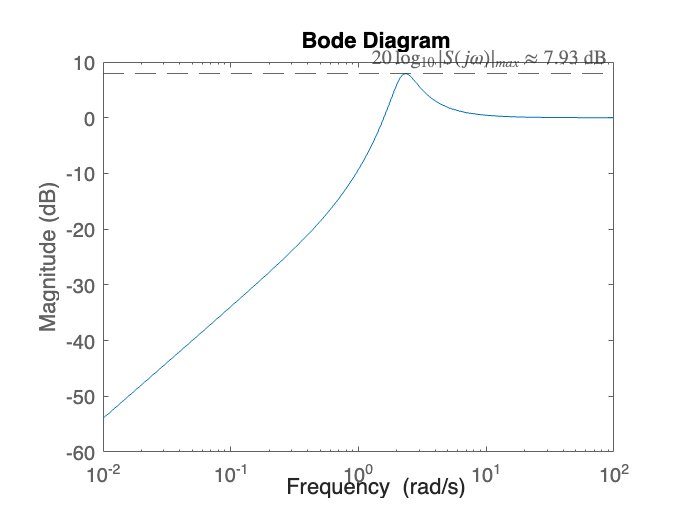

clear
s = tf('s');

L = 5/s/(s+1);
S = 1/(1+L);

figure, hold on
bodemag(S)
yline(7.93,'--','$20\log_{10}|S(j\omega)|_{max}\approx 7.93$ dB','Interpreter','latex')

magS_max = 10^(7.93/20)

magS_max = 2.4917

The maximum value of the sensitivity function is found to be 

$20\log_{10}|S(j\omega)|_{max}\approx 7.93$ dB,

or $\left| S(j\omega)\right|_{max}\approx 2.49$ in arithmetic units. The stability margin can then be determined as

 $s_M=\frac{1}{\left| S(j\omega)\right|_{max}}=\frac{1}{2.49}=0.4$.

####  Question 1: Determine the maximum value of the sensitivity function, $\left| S(j\omega)\right|_{max}$, in arithmetic units, when $L(s)=\frac{12}{s(s+1)(s+20)}$.

%Code block (if required)


####  Question 2: Using your answer from Question 1, determine the stability margin of the closed-loop system when $L(s)=\frac{12}{s(s+1)(s+20)}$.

%Code block (if required)


### Sensitivity M circles in the complex plane

The previous section has shown that there is a relationship between circles originating at the critical point and the magnitude response of the sensitivity. Following from this, if want to determine if the magnitude response of the sensitivity function is ever equal to some value $M$, namely

$\left| \frac{1}{1+L(j\omega)}\right| = M$,

then we can draw a circle centred on the critical point, with radius $\frac{1}{M}$, and if $L(j\omega)$ intersects this circle, then $S(j\omega)$ will have a magnitude response of $M$ at the frequency corresponding to the intersection. However, if $L(j\omega)$ never intersects the circle, then $S(j\omega)$ never has a magnitude response of $M$.

The code below generates sensitivity $M$ circles for $M \in \{0.5,1,2\}$.

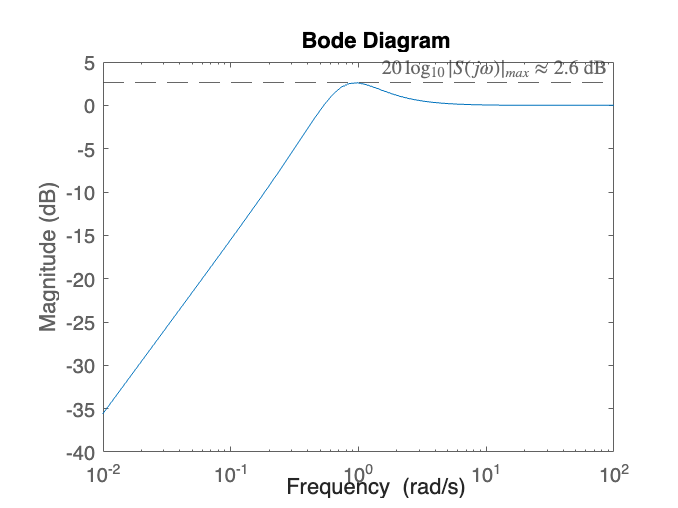

magS_max = 1.3490

clear


M_array=[0.5 1 2];
the = (0:1:360)*pi/180;


s_m = 0.7413

figure, hold on
for M=M_array
    circ = -1+1/M*exp(1i*the);
    plot(real(circ),imag(circ),'-',lineWidth=2)
end
plot(-1,0,'ro',MarkerFaceColor='r')
text(-1,-.1,'-1','Color','r')
xline(0,'-'),yline(0,'-')
legend('M=0.5','M=1','M=2')
axis equal

#### Example

*Using the Nyquist diagram, determine whether the sensitivity function ever has a gain that exceeds *$M=1.5$* when *$L(s)=\frac{1}{s(s+0.8)}$*.*

The code below generates the locus of $L(j\omega)$, as well as sensitivity $M$ circles, which have a corresponding radius of $\frac{1}{M}$.

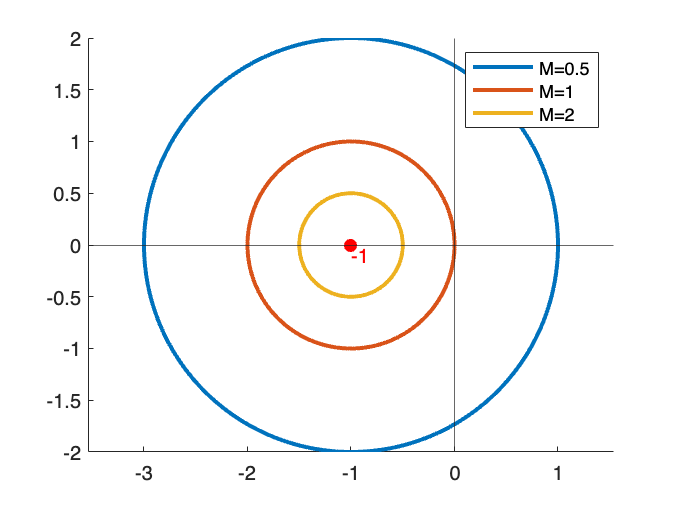

clear
s = tf('s');
L = 1/s/(s+0.8);

figure, hold on
plotoptions= nyquistoptions('cstprefs') ;   % default options
plotoptions.ShowFullContour = 'off';        % exclude negative frequencies
nyquist(L,plotoptions)

the = (0:1:360)*pi/180;

M = 1.5;
circ = -1+1/M*exp(1i*the);
plot(real(circ),imag(circ),'-',lineWidth=2)

xlim([-2,1]),ylim([-2,1])
axis equal

When $M=1.5$, resulting in a circle with radius of $\frac{2}{3}$, the $L(j\omega)$ locus does intersect the circle, which means that the sensitivity is larger than $M=1.5$ for a range of frequencies (when the locus resides within the $M=1.5$ circle). If we increase the value of $M$ using the code above, we will see that eventually $L(j\omega)$ will not intersect the resulting circle, which will represent the maximum gain of the sensitivity function.

We can plot the Bode magnitude response of $S(s)=\frac{1}{1+L(s)}$ using the code below.

S = 1/(1+L);

figure, hold on
bodemag(S)
yline(20*log10(M),'--k',['$M_{dB}=20\log$', num2str(M),'$\approx$',num2str(20*log10(M),2)],'Interpreter','latex')
grid on

As expected, the sensitivity function has a gain that exceeds $1.5$.

### The inverse Nichols chart

We can also represent the sensitivity $M$ circle boundaries in the log-polar plane as follows. Rearranging

$\left| \frac{1}{1+L(j\omega)}\right|= \frac{1}{\left|1+L(j\omega)\right|} = M$,

we can can define the relationship of

$|L(j\omega)+1|=\frac{1}{M}$.

As before, the equation above represents a circle, centred at $c=-1$ (the critical point in the complex plane), with a radius of $r=\frac{1}{M}$, which gives us an equivalent representation of 

$|L(j\omega)-c|=r$.

We can then solve for $L(j\omega)$ as

$\begin{array}{rl}
L(j\omega)
&=c+re^{j\phi},\\
&=-1+\frac{1}{M}e^{j\phi},
\end{array}$,

where $\phi\in \left[0,2\pi\right]$ is a parameter that we must sweep through in order to draw the circle that describes all solutions of $|L(j\omega)+1|=\frac{1}{M}$. The log-polar plot requires determining magnitude response (in dB) and phase angle (in degrees) or $L(j\omega)$, which we then determine using

$\begin{array}{rl}
|L(j\omega)|_{dB}
&=20\log_{10}\left|-1+\frac{1}{M}e^{j\phi}\right|
\end{array}$,

and

$\begin{array}{rl}
\angle L(j\omega)
&=\angle \{-1+\frac{1}{M}e^{j\phi}\}\frac{180}{\pi}
\end{array}$.

The code block below generates the resulting grid lines in the log-polar plot for a range of $M$ values.

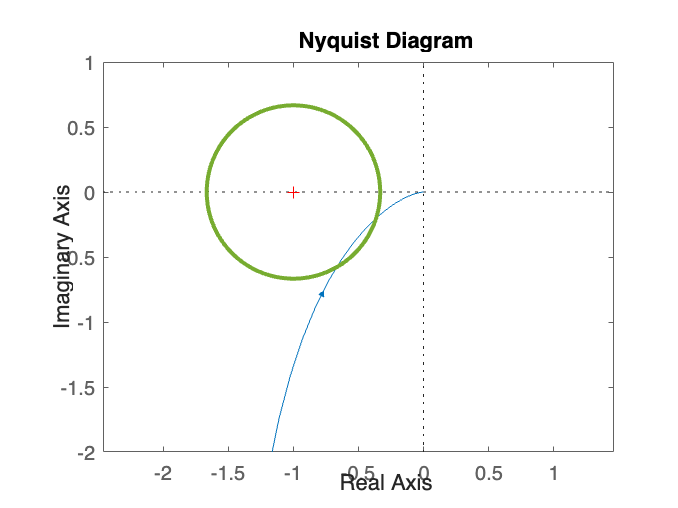

clear
M_array=[0.1 0.3 0.5 .7 1 2];

figure, hold on
for M=M_array

    phi = linspace(0,2*pi,1e4);

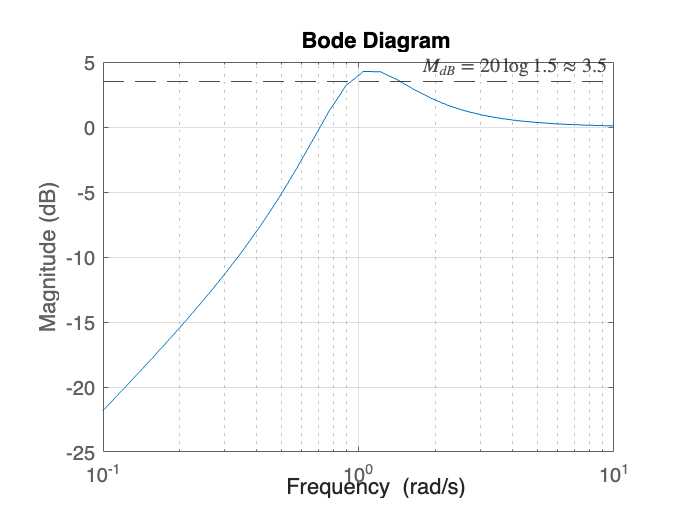

    c = -1;
    r = 1/M;
    L = c + r*exp(1i*phi);

    mag_L = 20*log10( abs(L) );
    phi_L = angle( L )*180/pi;
    for i=1:length(phi_L)
        if( phi_L(i) > 0), phi_L(i) = phi_L(i)-360; end

    end
    
    plot( phi_L(2:end-1),mag_L(2:end-1),LineWidth=2 )
end
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$M=0.1$','$M=0.3$','$M=0.5$','$M=0.7$','$M=1$','$M=1.2$','Interpreter','latex',Location='southeast')
axis tight
grid on


What we should first notice is that $M$ circles in the complex plane map to warped boundaries in the log-polar plane. We can still imagine them as "closed shapes", where the resulting grid lines that span the entire phase range close off entire regions below them. We also see that as the $M$ values increase, the boundaried regions shrink and approach the critical point (represented with a red dot), as was the case with the $M$ circles in the complex plane. When grid lines corresponding to the magnitude response of $S(j\omega)$ are overlaid in the log-polar plane, we refer to this type of plot as an **inverse Nichols chart**.

Assuming we can generate these grid lines in the log-polar plane, we can then make assertions about the magnitude response of $S(j\omega)$ when the response of $L(j\omega)$ is also present in the log-polar plane.

#### Example

*Using the inverse Nicholas chart, determine whether the sensitivity function ever has a gain that exceeds *$M=1.5$* when *$L(s)=\frac{1}{s(s+0.8)}$*.*

Note that this is the same example as before. The code below generates the locus of $L(j\omega)$, as well as grid lines for the warped sensitivity $M$ circles.

clear
s = tf('s');
Ls = 1/s/(s+0.8);

M = 1.5;

phi = linspace(0,2*pi,1e4);
c = -1;
r = 1/M;
L = c + r*exp(1i*phi);

mag_L = 20*log10( abs(L) );
phi_L = angle( L )*180/pi;
for i=1:length(phi_L)
    if( phi_L(i) > 0), phi_L(i) = phi_L(i)-360; end
end

figure, hold on
nichols(Ls)
plot( phi_L(2:end-1),mag_L(2:end-1),'-b',LineWidth=2 )
plot(-180,0,'ro',MarkerFaceColor='r')

The $L(j\omega)$ locus is shown to intersect the $M=1.5$ grid line (matching our previous assessment), which means that the sensitivity function will have a magnitude response that exceeds $1.5$ for frequencies that place $L(j\omega)$ within the contour. We can also see that increasing the $M$ value sufficiently will eventually result in no intersection, which means that our sensitivity gain is limited, as shown in the corresponding Bode magnitude response below.

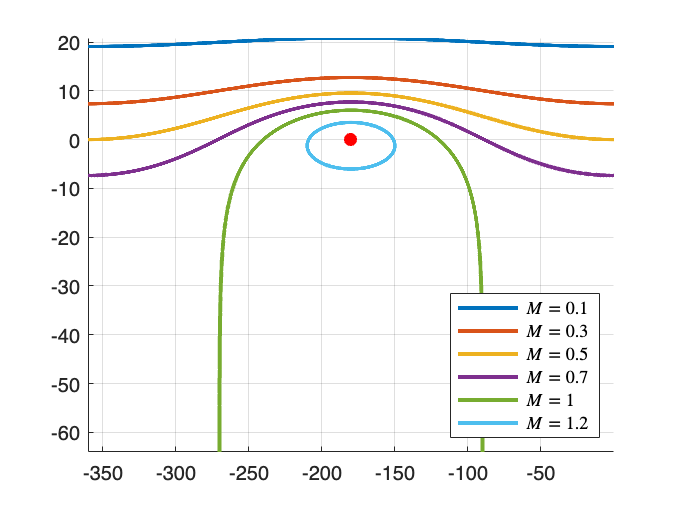

S = 1/(1+Ls);


figure, hold on
bodemag(S)
yline(20*log10(M),'-b',['$M_{dB}=20\log$', num2str(M),'$\approx$',num2str(20*log10(M),2)],'Interpreter','latex','LineWidth',2)
grid on
ylim([-25 15])

####  Question 3: Using the inverse Nichols chart, determine whether the sensitivity function ever has a gain that exceeds $M=1.7$ when $L(s)=\frac{12}{s(s+1)(s+20)}$.

%Code block (if required)


## Complementary sensitivity in the frequency domain

### Design objective

As the name implies, the sensitivity function and complementary sensitivity functions are related by

$S(s)+T(s)=1$,

where the complementary sensitivity function is defined as

$T(s)=\frac{L(s)}{1+L(s)}$.

Recall, with reference to the block diagram below, that the output response is related to all exogenous signals by


$$\begin{array}{rl}
Y(s) 
&= \frac{P(s)G(s)}{1+P(s)G(s)}R(s)+\frac{P(s)}{1+P(s)G(s)}D(s)-\frac{P(s)G(s)}{1+P(s)G(s)}N(s),\\
&= T(s)R(s)+PS(s)D(s)-T(s)N(s),\\
\end{array}$$


where the complementary sensivity function describes the mapping from reference $R(s)$ and noise $N(s)$ to the output $Y(s)$.

As previously discussed, we would like to make $|T(j\omega)|\approx 1$for the low-frequency range where we expect $R(s)$ to act, as this will give us good reference tracking for sufficiently low-frequency reference signals. We then want to make $|T(j\omega)|\ll 1$for the high-frequency range where we expect high-frequency noise term $N(s)$ to act, in order to avoid noise making its way to the output of our system. An idealised Bode magnitude response of the complementary sensitivity function is shown below.

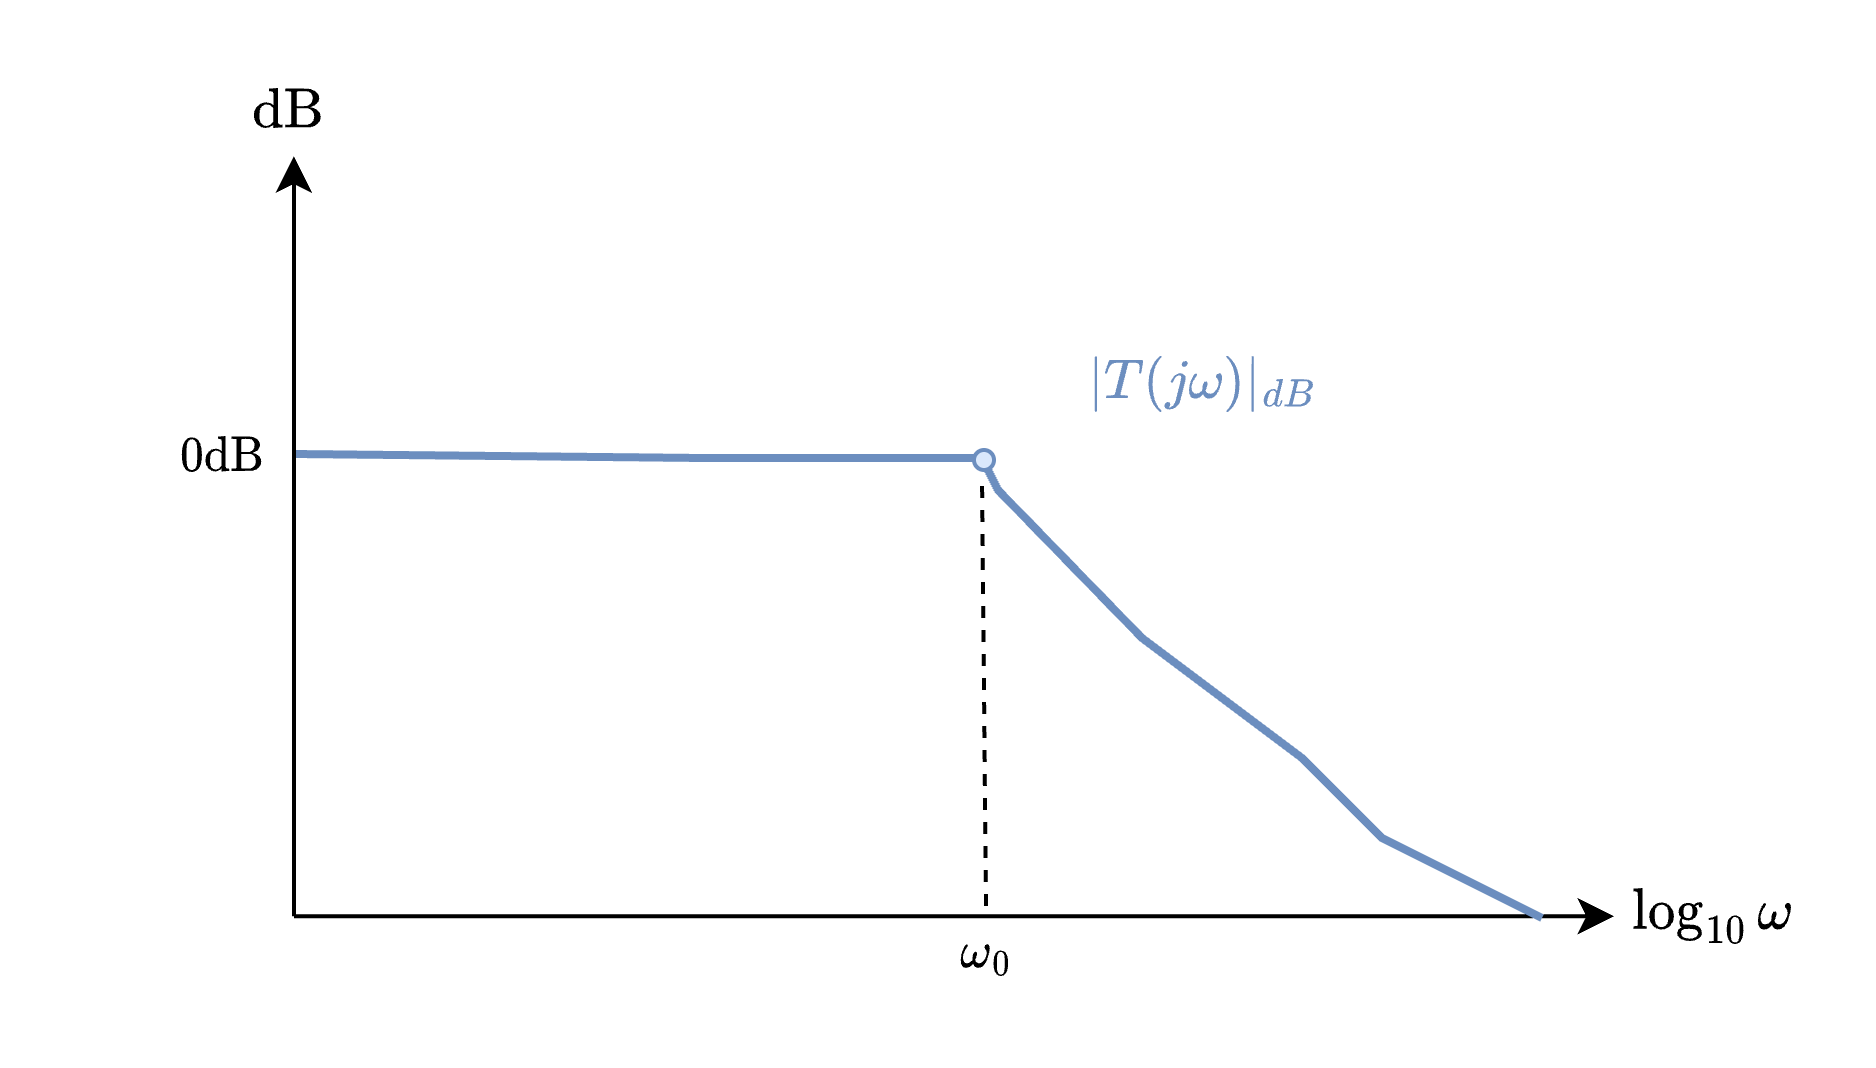

Given that we only have agency over the structure of $G(s)$, we therefore want to adjust $L(s)=P(s)G(s)$ in order to shape the behaviour of $T(s)$ as required. In order to do this, we need to be able to define design specifications on $L(s)$ that relate directly to design specifications on $T(s)=\frac{L(s)}{1+L(s)}$. With this in place, we can then adjust $L(s)$ using $G(s)$, based on the design requirements of $T(s)$, such as bandwidth, overshoot, and steady-state error.

### The Nichols chart

Similar to the sensitivity $M$ circles that we used previously to describe the sensitivity magnitude response, we can assign a complementary sensitivity $M$ circle as

$|T(j\omega)|=\left|\frac{L(j\omega)}{1+L(j\omega)}\right|=M$. 

If we now divide the numerator and denominator of $|T(j\omega)|$ by $L(j\omega)$ we obtain

$\left|\frac{1}{1/L(j\omega)+1}\right|=M$. 

We can then make a variable substitution of 

$K(j\omega)=\frac{1}{L(j\omega)}$,

which results in 

$\left|\frac{1}{K(j\omega)+1}\right|=M$. 

With reference to **Section 11.2.3**, the above equation has the form of a sensitivity function, albeit with $K(j\omega)$ instead of $L(j\omega)$. We can therefore use our results from the previous section to solve the above equation for $K(j\omega)$, namely

$\begin{array}{rl}
|K(j\omega)|_{dB}
&=20\log_{10}\left|-1+\frac{1}{M}e^{j\phi}\right|
\end{array}$,

and

$\begin{array}{rl}
\angle K(j\omega)
&=\angle \{-1+\frac{1}{M}e^{j\phi}\}\frac{180}{\pi}
\end{array}$.

If we were to plot this information in the log-polar plane, we would end up with the same grid lines as before. However we are interested in plotting the grid lines of $L(j\omega)$ resulting from $|T(j\omega)|=\left|\frac{L(j\omega)}{1+L(j\omega)}\right|=M$. Noting that $K(j\omega)=\frac{1}{L(j\omega)}$, the magnitude response relationship will therefore be

$|K(j\omega)|_{dB}=-|L(j\omega)|_{dB}$,

and the phase response relationship will be

$\angle K(j\omega)=-\angle L(j\omega)$.

In other words, once we have determined the (logarithmic) magnitude and phase response of $K(j\omega)$ and have plotted them in the log-polar plane (which would look like sensitivity grid lines), we then need to turn our log-polar plot "upside down", which switches the logarithmic gain and phase as per the equations above. In fact, because the grid lines resulting from sensitivity $M$ circles are symmetric about the $-180^\circ$ phase line in the log-polar plane, we really just need to reflect our sensitivity grid lines about the $0$ dB x-axis in order to obtain complementary sensitivity grid lines.

The code block below generates the resulting grid lines in the log-polar plot for a range of $M$ values.

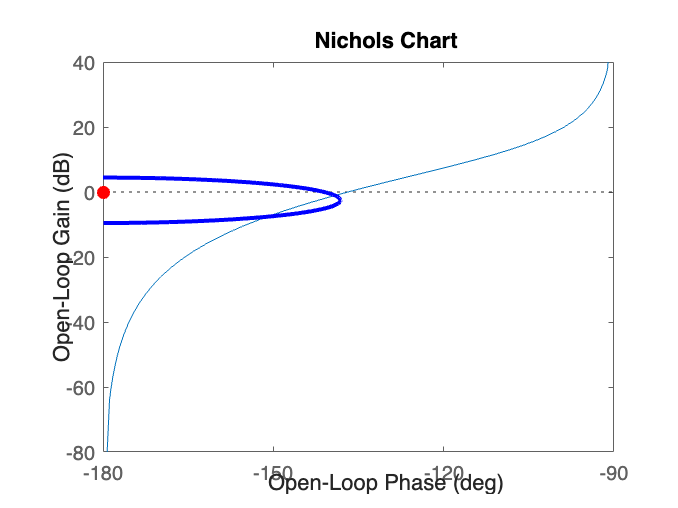

clear
M_array=[0.1 0.3 0.5 .7 1 2];

figure, hold on
for M=M_array

    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M;
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end
    
    plot( phi_K(2:end-1),-mag_K(2:end-1),LineWidth=2 )
end
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$M=0.1$','$M=0.3$','$M=0.5$','$M=0.7$','$M=1$','$M=1.2$','Interpreter','latex')

axis tight
grid on

Note that these grid lines are equivalent to sensitivity grid lines that have been reflected about the $0$dB x-axis. We can therefore plot $L(j\omega)$ on a log-polar plot and then have a way to determine what the corresponding $|T(j\omega)|$ will be based on when $L(j\omega)$ intersects a particular grid line. When displaying the grid lines of the complementary sensitivity magnitude response on a log-polar plot, we refer to this as a **Nichols chart**.

#### Example

*Using the Nicholas chart, determine whether the complementary sensitivity function ever has a gain that exceeds *$M=1.5$* when *$L(s)=\frac{1}{s(s+0.8)}$*.*

The code below generates the locus of $L(j\omega)$, as well as grid lines for the warped complementary sensitivity $M$ circles.

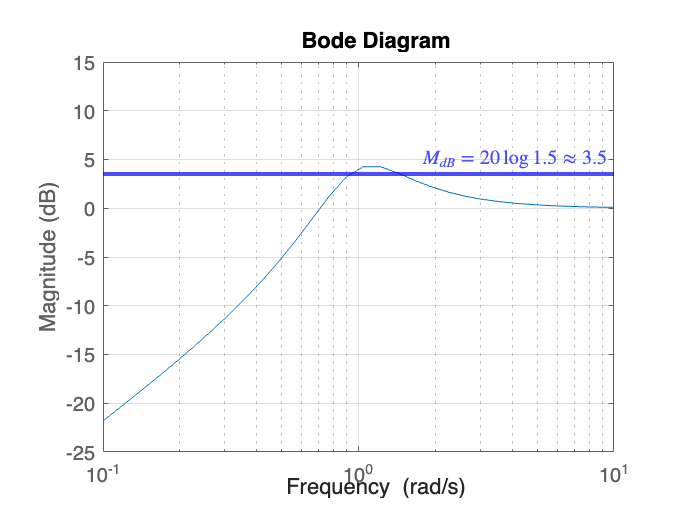

clear
s = tf('s');
L = 1/s/(s+0.8);

M = 1.5;

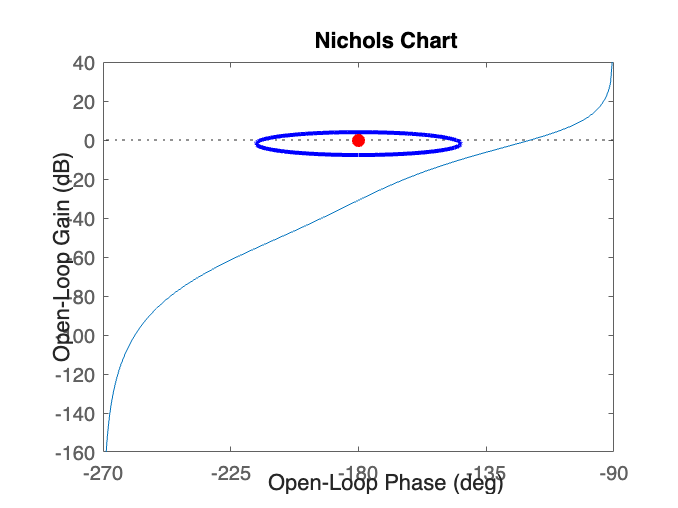


phi = linspace(0,2*pi,1e4);
c = -1;
r = 1/M;

K = c + r*exp(1i*phi);

mag_K = 20*log10( abs(K) );
phi_K = angle( K )*180/pi;
for i=1:length(phi_K)
    if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
end

figure, hold on
nichols(L)
plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
plot(-180,0,'ro',MarkerFaceColor='r')

The $L(j\omega)$ locus is shown to not intersect the $M=1.5$ grid line, which means that the complementary sensitivity function will never have a magnitude response that exceeds $1.5$. The Bode magnitude response of $T(s)$ confirms our answer.

T = L/(1+L);

figure, hold on
bodemag(T)
yline(20*log10(M),'--b',['$M_{dB}=20\log$', num2str(M),'$\approx$',num2str(20*log10(M),2)],'Interpreter','latex','LineWidth',2)
grid on

When using MATLAB's `nichols `function in conjunction with the `grid on` command, MATLAB automatically generates the Nichols chart, albeit with complementary sensitivity $M$circles in decibels. Complementary sensitivity phase lines are also generated, but we will not focus on this for this course. An example is shown using the code below.

figure
nichols(L)
grid on

####   **Task: In the code block below, generate the Nichols chart of **$L(s)=\frac{12}{s(s+1)(s+20)}$ using the `nichols` function and `grid on`. Use a y-axis limit of `ylim([-20 40]).`

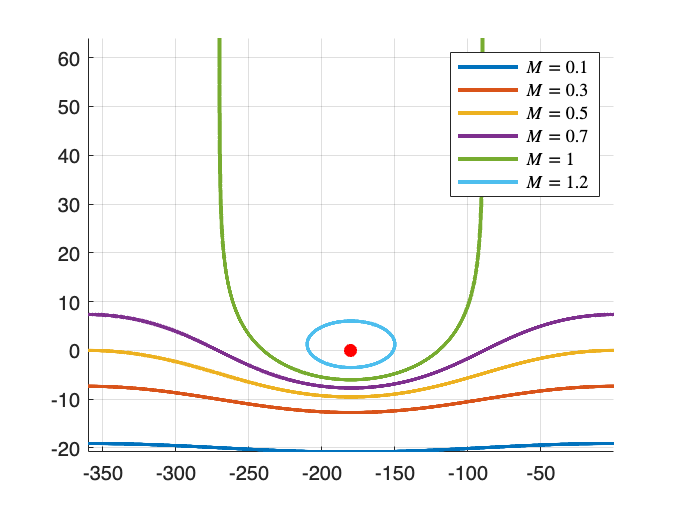

%Code block for task

####  Question 4: Using the Nichols chart generated by your code block above, determine whether $T(s)$ ever has a gain greater than $M=1.06$.

%Code block (if required)


## Closed-loop design specifications

We have now developed a means of determining the magnitude response of $S(j\omega)$ or $T(j\omega)$ based on visualisation of $L(j\omega)$ in a log-polar plot. The next step is to understand how to convert user specifications into design specifications on the closed-loop system. If we can place design constraints on $T(j\omega)$ or $S(j\omega)$, we can then convert it to design constraints on $L(j\omega)$, as before.

### Degree of closed-loop systems

While we do not yet possess the tools to manipulate $L(s)$ in a sensible way, we will eventually do so in order to shape $T(s)$ or $S(s)$. An important thing to be aware of is that the order of $L(s)$ will dicate the order of $T(s)$ and $S(s)$. If the loop transfer function is given by

$L(s)=\frac{N(s)}{D(s)}=\frac{a_0+a_1s+a_2s^2+...+a_ms^m}{b_0+b_1s+b_2s^2+...+b_ns^n}$,

where $n\geq m$, then 

$T(s)=\frac{L(s)}{1+L(s)}=\frac{N(s)/D(s)}{1+N(s)/D(s)}=\frac{N(s)}{N(s)+D(s)}$,

and

$S(s)=\frac{1}{1+L(s)}=\frac{1}{1+N(s)/D(s)}=\frac{D(s)}{N(s)+D(s)}$.

So the order of $N(s)+D(s)$, which is the denominator polynomial of $S(s)$ and $T(s)$, will always be less than or equal to the order of $D(s)$, depending on whether there are cancellations in $N(s)+D(s)$. This means that if we know what order $L(s)$ will take, we can then expect equivalent order from $T(s)$ and $S(s)$.

### User specifications

**User specifications** are often given as high-level closed-loop objectives. This can include various system parameters that we have already considered, such as:

- steady-state error

- maximum percentage overshoot

- peak time

- settling time

- gain margin and phase

- stability margin

- closed-loop bandwidth

Specifications (5)-(7) are easy to determine in the frequency domain and have already been covered in some detail, whereas (2)-(4) are time-domain specifications that must be suitably represented in the frequency domain. Specification (1) is also a time-domain specification, but we have already shown that we can interpret steady-state error in the frequency domain by consulting the low-frequency behaviour of $|L(j\omega)|$.

### Controller synthesis for first-order systems

Assuming our plant is first-order and strictly proper, namely

$P(s)=\frac{a_0}{b_0+b_1s}$,

and we intend to design a proportional controller of the form $G(s)=K$, then $L(s)=P(s)G(s)$ will also be a first-order system, given by

$L(s)=K\frac{a_0}{b_0+b_1s}$.

The corresponding complementary sensitivity function will follow as a first-order system:

$T(s)=\frac{L(s)}{1+L(s)}=\frac{Ka_0}{Ka_0+b_0+b_1s}$.

Under these conditions, we can specify a desired closed-loop reference model, $M(s)$, which captures the user specifications for the reference to output transfer behaviour. First-order systems are known to not exhibit percentage overshoot, so we are only concerned with settling time and steady-state error. Rewriting $T(s)$ in its canonical form gives

$T(s)=\frac{Ka_0}{Ka_0+b_0+b_1s}=\frac{A_s}{1+sT_c}$,

where

$A_s=\frac{Ka_0}{Ka_0+b_0)}$, 

and

$T_c = \frac{b_1}{Ka_0+b_0}$.

Remembering that the settling time of a first-order system is given by $T_s\approx 4T_c$, we can then ensure that our closed-loop first-order system will be sufficiently fast if 

$4\frac{b_1}{Ka_0+b_0}\leq T_s$,

where $T_s$ is a user specification and $K$ is the only free parameter. Additionally, if a steady-state error percentage is prescribed, given by

$\frac{e(\infty)}{r(\infty)}=\frac{r(\infty)-y(\infty)}{r(\infty)}\leq \beta$,

then noting that $y(\infty)=A_sr(\infty)$, the equation above reduces to

$\frac{e(\infty)}{r(\infty)}=\frac{r(\infty)-y(\infty)}{r(\infty)}=\frac{r(\infty)-A_sr(\infty)}{r(\infty)}=1-A_s\leq \beta$,

and hence

$A_s=\frac{Ka_0}{Ka_0+b_0}\geq 1-\beta$.

Alternatively, if the desired steady-state performance is given relative to a unit step, then we can use final-value theorem, namely

$e(\infty)=\lim_{s\rightarrow 0}sE(s)=\lim_{s\rightarrow 0}\frac{b_0+b_1s}{Ka_0+b_0+b_1s}=\frac{b_0}{Ka_0+b_0}$.

The two constraints on $K$ can be solved individually, and then the intersection of the two solution spaces will describe the admissible $K$ values. For sake of reducing the size of the control action, we often then choose the smallest viable $K$ value.

#### Example

*Synthesize a proportional controller of the form *$G(s)=K$*, which results in a settling time of *$T_s\leq 10$* seconds, with a steady-state error of *$e(\infty)\leq 0.1$ for unit step reference signal*, for the system *$P(s)=\frac{2}{1+2s}$*.*

For the settling time constraint, we require that

$4\frac{b_1}{Ka_0+b_0}=4\frac{2}{2K+1}\leq 10$,

which results in $K\geq -0.1$. For the steady-state error specification, we require that

$\frac{b_0}{Ka_0+b_0}=\frac{1}{2K+1}\leq 0.1$,

which gives $K\geq 4.5$. The intersection of solution spaces for the feedback controller gain is $K\geq 4.5$.

The step response of the closed-loop system is generated using the code below, which shows that the closed-loop system adheres to both constaints.

clear
s = tf('s');

P = 2/(1+2*s);
K = 4.5;
L = P*K;
T = feedback(L,1);

figure,hold on
step(T)
impulse(1/s)
ylim([0 1.2])
legend('$y(t)$','$r(t)$','Interpreter','latex')

For values of $K\leq 4.5$, the steady-state error will not be met. Note that because we only have a single parameter, $K$, to vary, we cannot in general meet both the settling time and steady-state error requirements at equality. Instead, there will be overdesign for one of the two specifications.

####  Question 5: Determine the minimum $K$ value required to satisfy $e(\infty)\leq \alpha$ when $P(s)=\frac{a_0}{b_0+b_1s}$.

%Code block (if required)


####  Question 6: Determine the minimum $K$ value required to satisfy $T_s\leq \beta$ when $P(s)=\frac{a_0}{b_0+b_1s}$.

%Code block (if required)


### Second-order reference models

Assuming $L(s)$ is at least second-order, then the design specifications of $T(s)$ can be suitably approximated by a $2^{nd}$-order reference model of the form

$M_A(s)=\frac{\omega_n^2}{s^2+2\zeta\omega_ns+\omega_n^2}$.

Note that the DC gain of $M_A(s)$ is chose as one, which means that step reference signals will be tracked with zero error at steady-state. 

If overshoot and settling time specifications are prescribed for the closed-loop system, then the corresponding $2^{nd}$-order frequency response magnitudes can be used to bound $|T(j\omega)|$.

Recall that the damping ratio of a second-order low-pass filter can be determined from the percentage overshoot specification by 

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$.

Additionally, the settling time is given by

$T_s=\frac{-\ln\left(0.02\sqrt{1-\zeta^2}\right)}{\zeta\omega_n}\approx \frac{4}{\zeta\omega_n}$,

which allows for determination of the naturaly frequency. $\omega_n$, if $T_s$ and $\zeta$ are known. Based on this, if the desired percentage overshoot and settling time specifications are

$\%OS\leq\alpha$,

$T_s\leq \beta$,

then one can use the above formulas to determine $M_A(s)$. Ideally we could simply set $T(s)=M_A(s)$ and then solve for $G(s)$, but $T(s)$ will, in general, have a different structure to $M_A(s)$, such as when there are more than two poles, or at least one zero. Instead, we can use our reference model to bound $|T(j\omega)|$, namely

$|T(j\omega)|\leq |M_A(j\omega)|$.

#### Example

*Determine a 2nd-order model that represents a system with a settling time of 5 seconds, percentage overshoot of *$25$*%, zero steady-state error for step inputs.*

Using the relevant formulas, we can determine the required damping ratio and natural frequency as

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.40$,

$\omega_n=\frac{4}{\zeta T_s}=1.98$.

The reference model follows as

$M_A(s)=\frac{3.93}{s^2+1.6s+3.93}$.

The code below generates the Bode magnitude response and step response of the reference model.

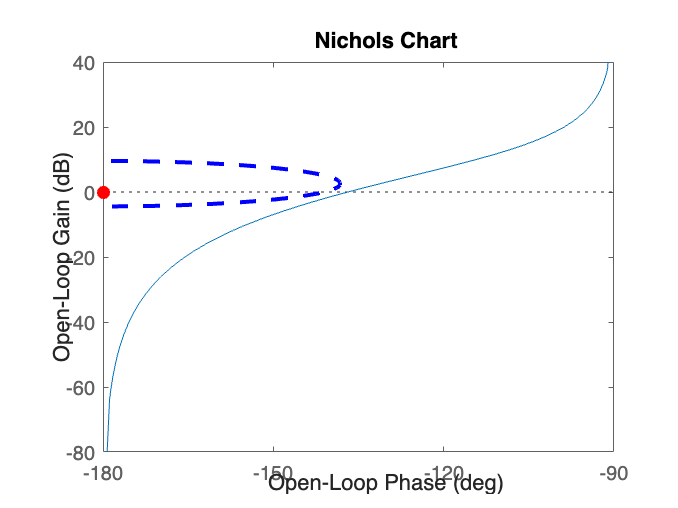

clear

OS = 25;
Ts = 5;

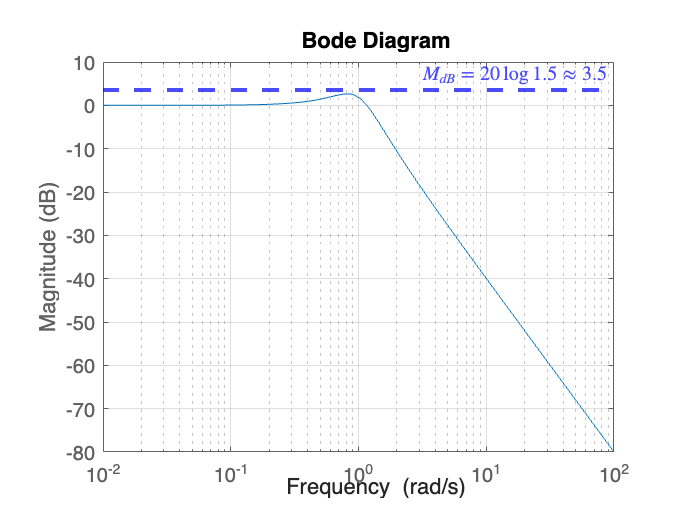


zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2)
wn = 4/zeta/Ts

s = tf('s');
M = wn^2/( s^2+2*zeta*wn*s+wn^2);
figure

bodemag(M)
figure
step(M)

####  Question 7: Determine a 2nd-order model that represents a system with a settling time of 10 seconds, percentage overshoot of $5\%$, and zero steady-state error for step inputs.

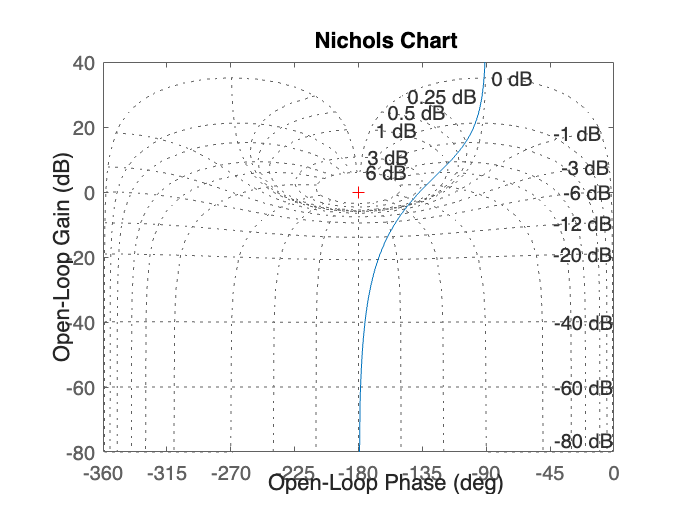

%Code block (if required)


### Above and below tracking bounds

If $T(s)$ is designed such that the equation above is adhered to, then we have some assurance that our closed-loop system will adhere to the overshoot specification. However, the settling time constraint is not strictly enforced, as there is nothing preventing $T(s)$ having a infinitesimally small bandwidth. To prevent this from happening, we also place a lower bound on the gain of $T(s)$, which results in 

$|M_B(j\omega)|\leq|T(j\omega)|\leq |M_A(j\omega)|$,

where $|M_B(j\omega)|$ represents the *stay-above *bound on $|T(j\omega)|$, and $|M_A(j\omega)|$ represents the *stay-below* bound, as shown below.

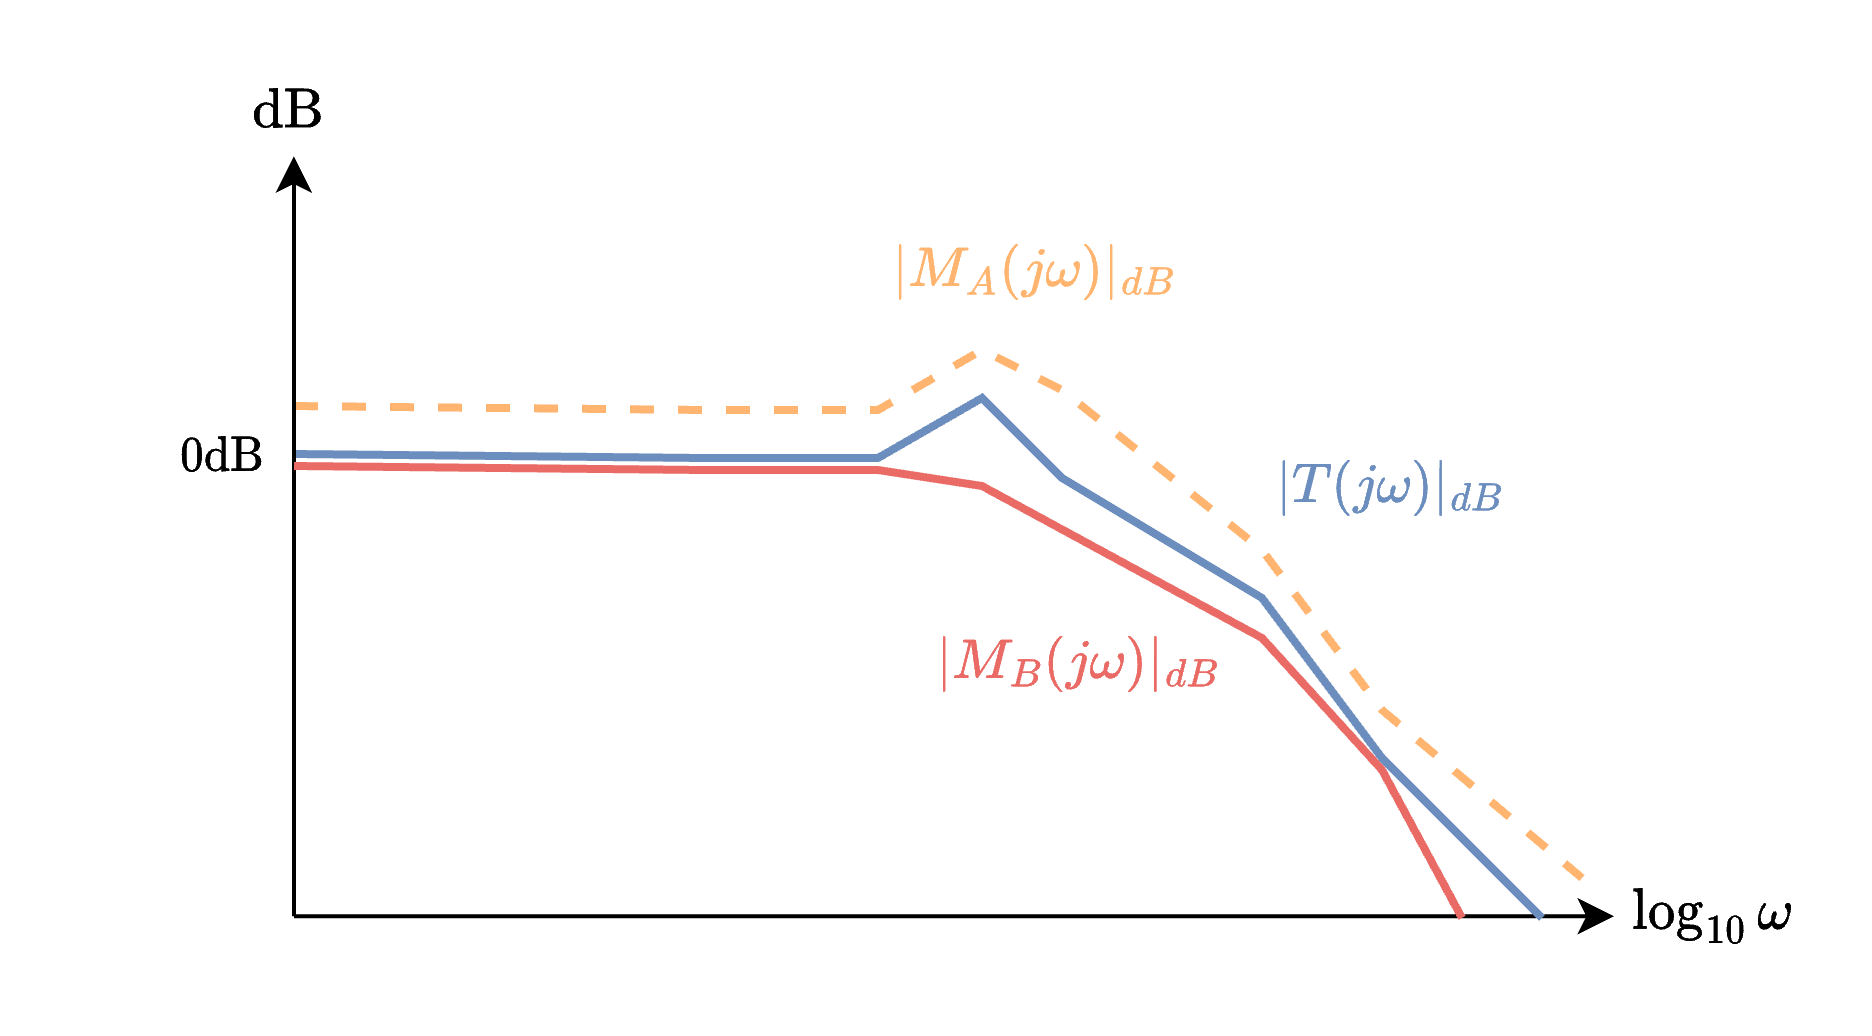

A valid design of $T(s)$ requires locating $|T(j\omega)|$ within the band made up by $|M_A(j\omega)|$ and $|M_B(j\omega)|$. 

####   **Task: Generate a Bode magnitude response graph that plots the magnitude responses of **$M_A(s) = \frac{0.34}{s^2+0.8s+0.34}$ and $M_B(s) = 0.71\frac{0.34}{s^2+1.5s+0.34}$ 

%Code block for task


####  Question 8: Submit your graph from the above task as your answer. Your student number should be the title of the image.

To simplify things, we will consider simplified above and below bounds on $|T(j\omega)|$. Specifically, we will employ a *stay-below* bound for the percentage overshoot specification, and a *stay-above *bound for the settling time specification.

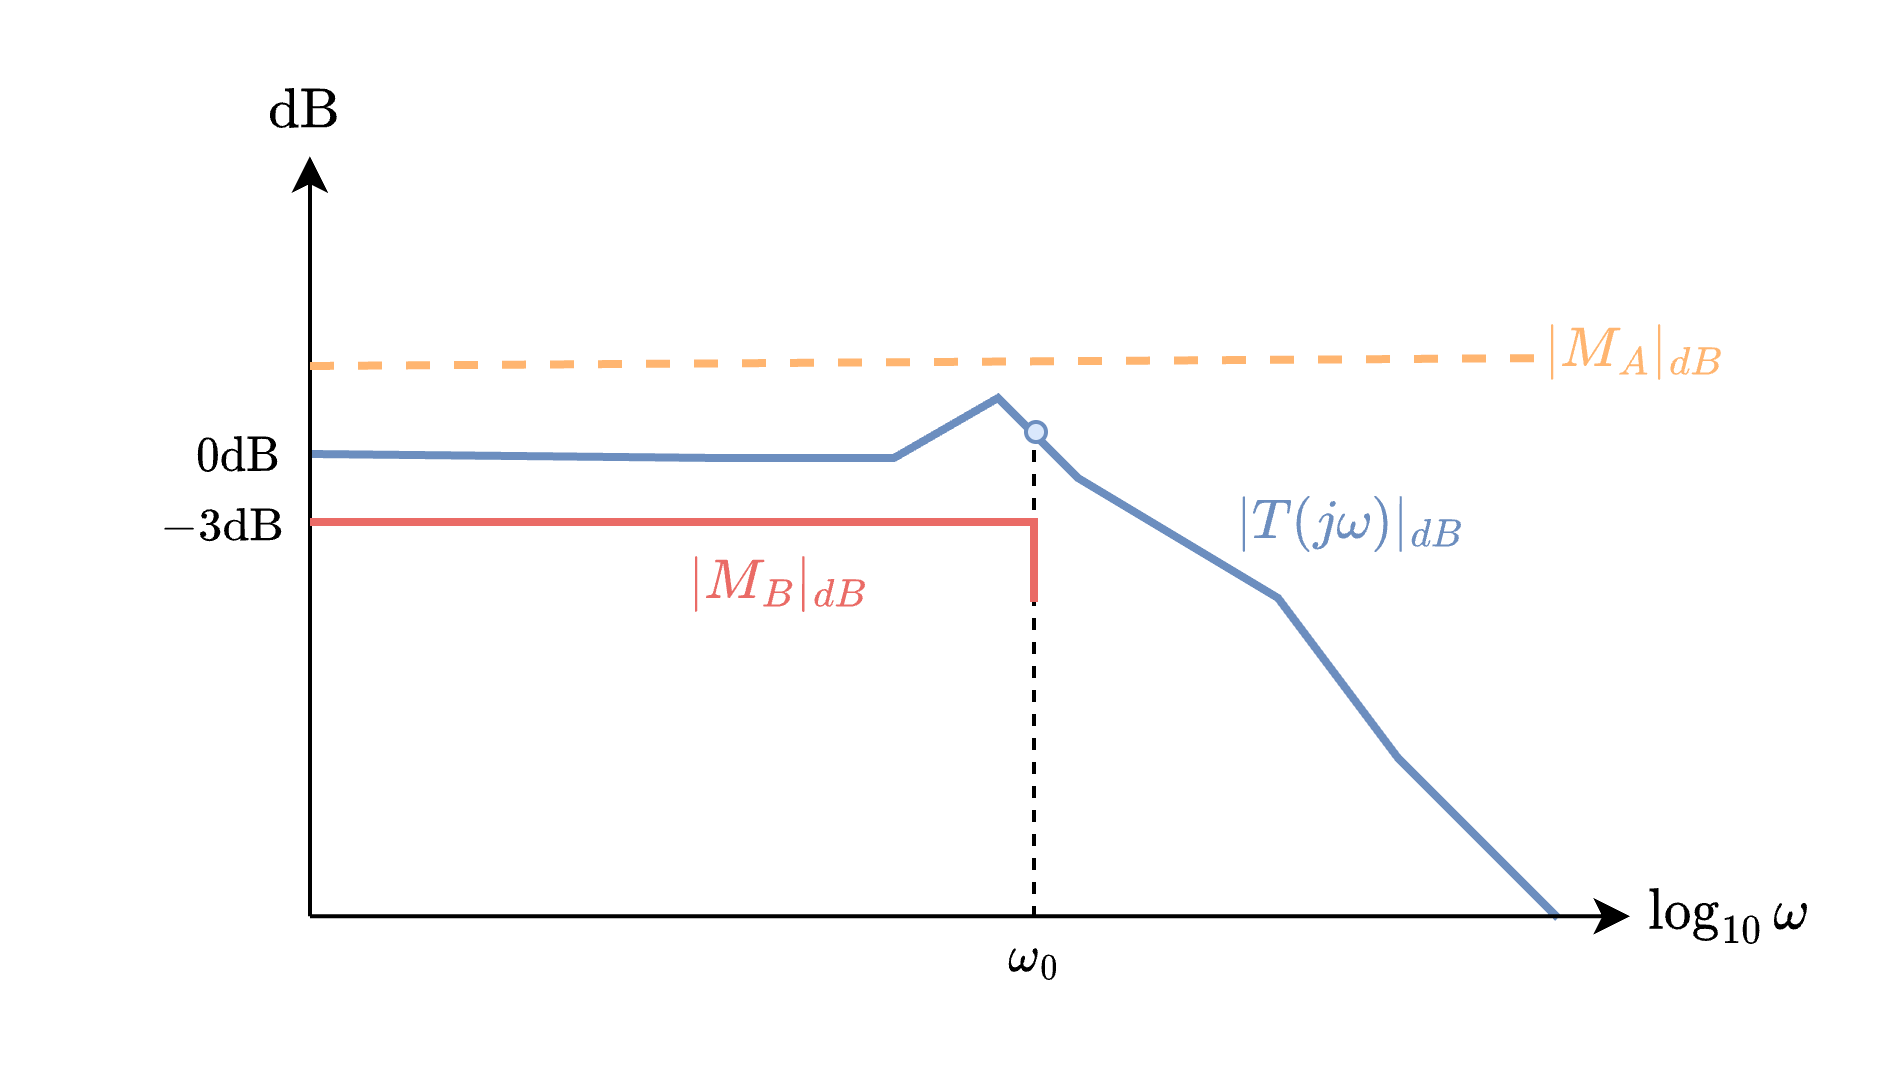

With reference to the figure above, $M_A$ is determined from the percentage overshoot specification and is considered for all frequencies. *Stay-above *bound $M_B$ is determined from the settling time constraint and enforces the appropriate closed-loop bandwidth of the complementary sensitivity function. Note that $M_B$ is only considered for $\omega\leq \omega_0$. That is, for frequencies outside of the desired closed-loop bandwidth, $|T(j\omega)|$ can become arbitarily small. In fact, based our previous discussions, we want $|T(j\omega)|\ll 1$ for frequencies outside of our desired passband. We could add an additional high-frequency bound, $M_{hf}$, to enforce this, as shown in the image below, but we will keep things simple with the two boundaries (for now). 

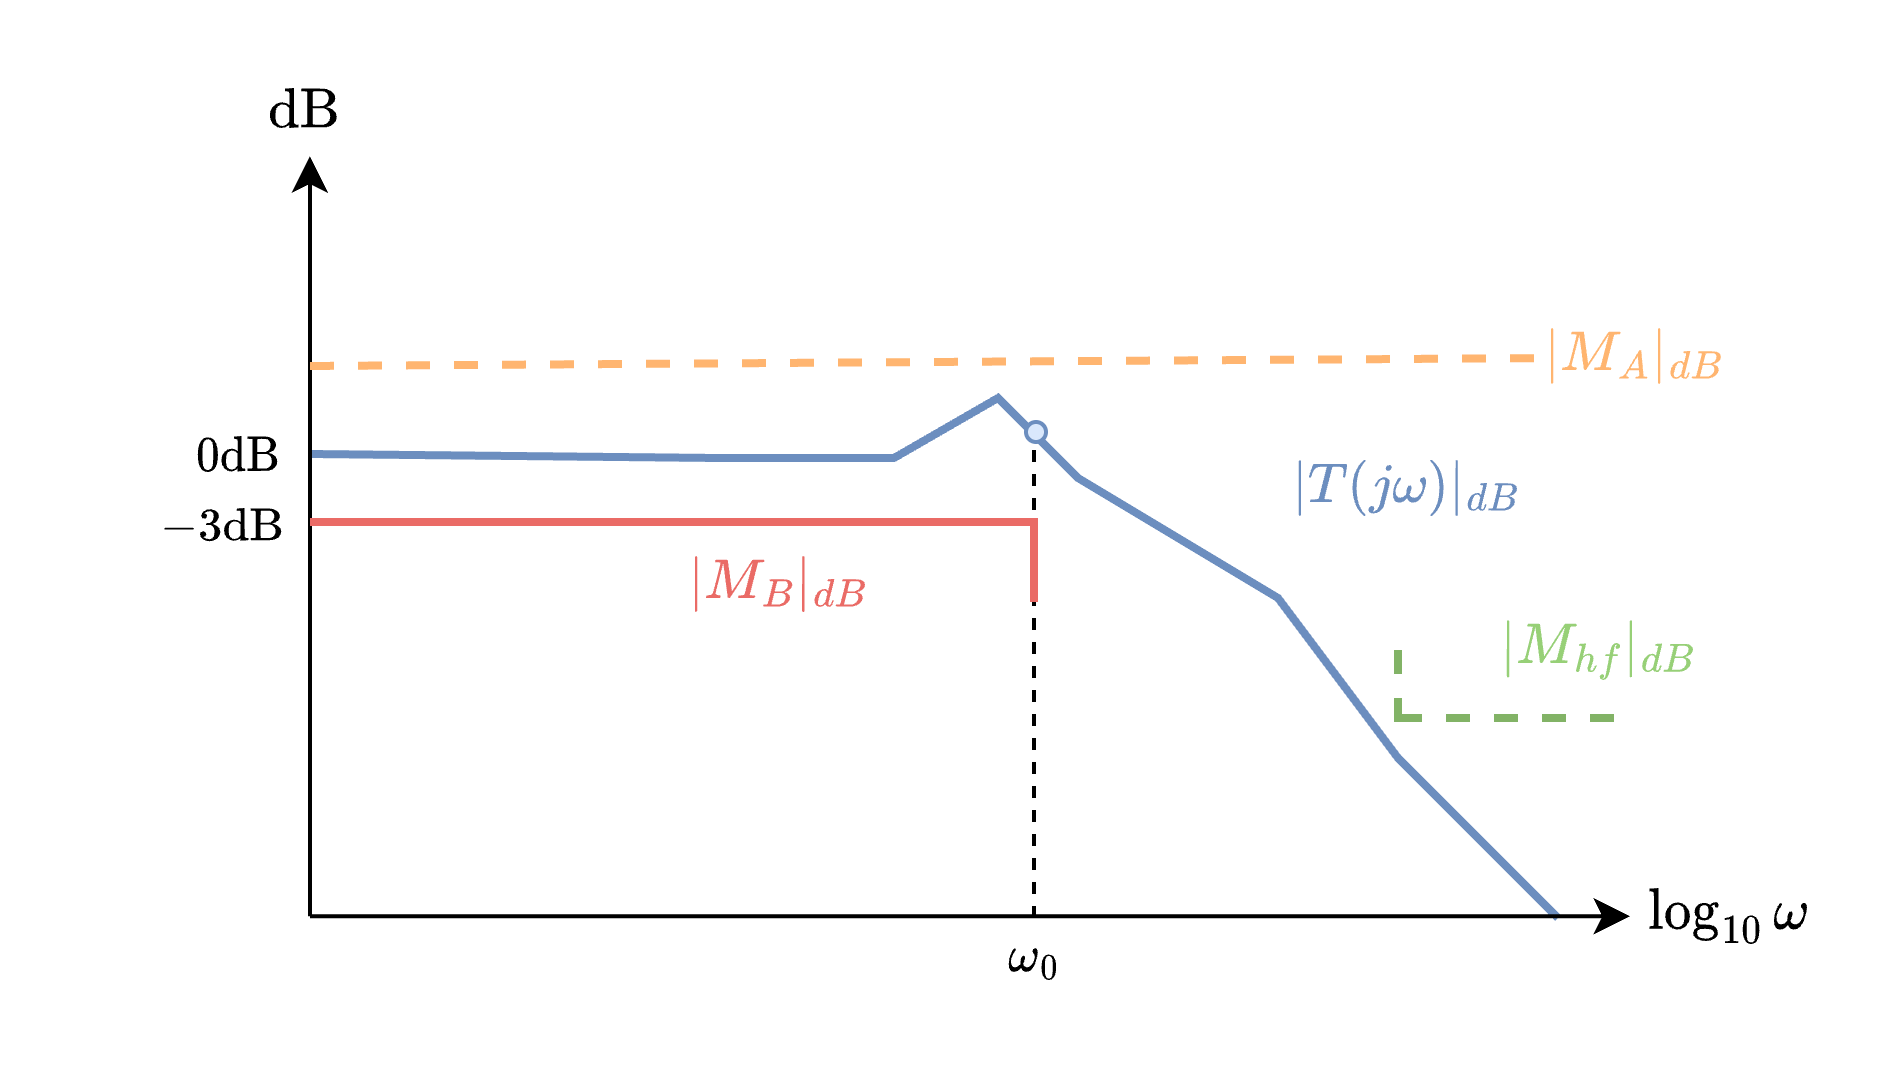

It is important to note that the approach above does not cater directly for the steady-stat error specification. Based on the diagram above, there is a non-zero tolerance for the DC gain of $T(j\omega)$. If a steady-state error specification is additionally given, then we must use our understanding of final-value theorem and type numbers to ensure the correct steady-state behaviour.

The all-frequency *stay-below *bound is calculated using

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}$,

which we previously determined as the peak magnitude response of a second-order low-pass filter. If a percentage overshoot specification is given, then we can use


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}$$


and then substitute the resulting $\zeta$ into the previous equation to determine $M_A$.

$M_B$ is generally set to $\frac{1}{\sqrt{2}}$, or $-3$ dB in logarithmic units, based on the definition of closed-loop bandwidth, but importantly, we will only consider the $M_B$ bound up until closed-loop bandwidth frequency $\omega_0$. To determine $\omega_0$, we first choose a damping ratio that results in a magnitude response similar to that of $|M_B(j\omega)|$. For this reason, we can choose any $\zeta\geq 0.71$, as this means that there will be no peak response for our lower bound. Choosing $\zeta=0.71$, for example, we can then calculate the natural frequency corresponding to a second-order settling time of $T_s$ using

$\omega_n=\frac{4}{\zeta T_s}$.

Following this, we can use the formula for the bandwidth frequency of a 2nd-order low-pass filter, namely,

$\omega_0=\omega_n\sqrt{ (1-2\zeta^2)+\sqrt{4\zeta^4-4\zeta^2+2}}$.

We then enforce $M_B$ for $\omega<\omega_0$ and $M_A~\forall \omega$.

#### Example

*Determine the simplified above and below bounds of a 2nd-order system with a settling time of 5 seconds and percentage overshoot of *$25$*%.*

Using the relevant formulas, we can determine the required damping ratio as

$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.40$,

which we use to determine the peak magnitude response:

$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.35$.

The natural frequency corresponding to a chosen damping ratio of $\zeta=0.71$ and desired settling time of $T_s=5$ seconds is

$\omega_n=\frac{4}{\zeta T_s}=1.98$ rad/s,

which allows us to determine the desired closed-loop bandwidth frequency as

$\omega_0=\omega_n\sqrt{ (1-2\zeta^2)+\sqrt{4\zeta^4-4\zeta^2+2}}=1.12$ rad/s.

The code below generates the Bode magnitude response of $M_A(j\omega)$ and $M_B(j\omega)$, as well as the corresponding simplified *stay-below* and *stay-above* bounds, respectively.

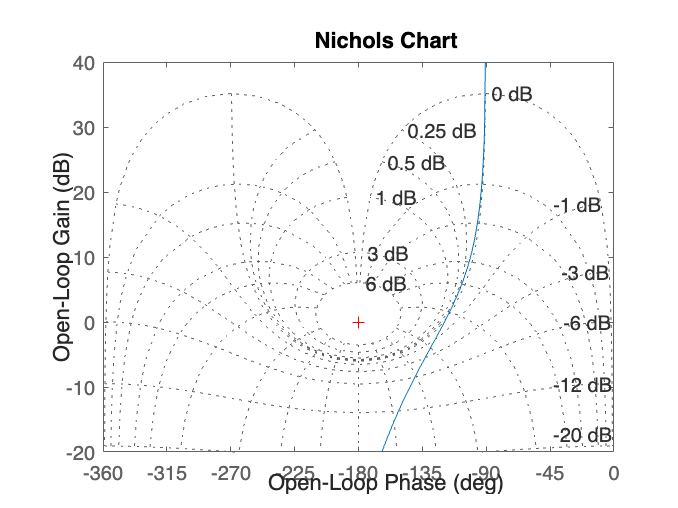

clear

s = tf('s');

%specifications

x = 1.0593

M_dB = 0.5061

OS = 25;
Ts = 5;

%stay-above bound
zeta = 0.71;
wn = 4/zeta/Ts;
M_down = wn^2/( s^2+2*zeta*wn*s+wn^2);
w0 = wn*sqrt( (1-2*zeta^2)+sqrt( 4*zeta^4-4*zeta^2+2 ) )


%stay-below bound
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2)
wn = 4/zeta/Ts
Ma = 1/( 2*zeta*sqrt(1-zeta^2));
M_up = wn^2/( s^2+2*zeta*wn*s+wn^2);

%plotting
figure, hold on
bodemag(M_up),bodemag(M_down,'g')

yline(20*log10(Ma),'--b',['$|M_A|_{dB}=20\log$', num2str(Ma,3),'$\approx$',num2str(20*log10(Ma),2)],'Interpreter','latex')
line([1e-2 w0],[-3 -3])
text(.05,-6,'$|M_B|_{dB}=-3$ dB, $\omega\leq \omega_0$','Interpreter','latex','Color','red')

####  Question 9: Determine the simplified above bound of a 2nd-order system with a settling time of 10 seconds and percentage overshoot of $10$%. Provide your answer to two decimal points.

%Code block (if required)


####  Question 10: Determine the desired closed-loop bandwidth, $\omega_0$, of the simplified lower bound, $M_B$, of a 2nd-order system with a settling time of 10 seconds and percentage overshoot of $10$%. Use a desired damping ratio of $\zeta=0.71$. Provide your answer to two decimal points.

%Code block (if required)


### Tracking bounds in the log-polar plane

Once $M_A$ and $M_B$ have been determined, we can then represent these constraints in the log-polar plane. We do this because we then have a clear relationship between $L(s)$, which we will be able shape via $G(s)$, whilst also being able to assess the adherence to the closed-loop specifications.

The code below generates the two boundaries, where the region enclosed by the blue dotted line represents a *stay-out *region for $|T(j\omega)|\leq M_A$, and the region enclosed by the green solid line represents the *stay-out *region for $|T(j\omega)|\geq M_B$.

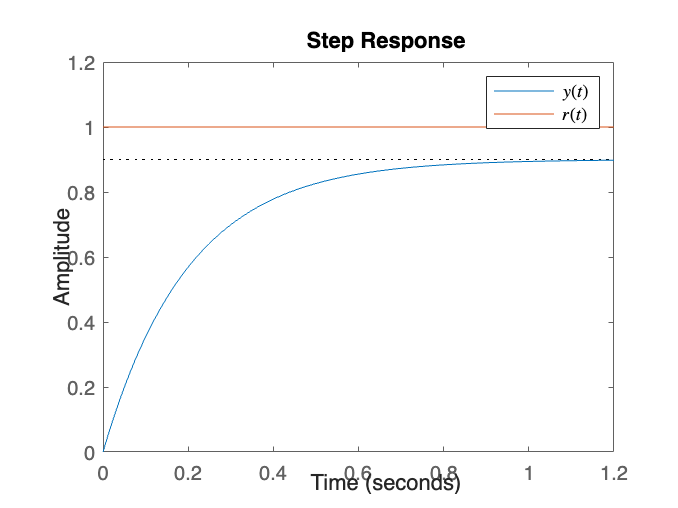

clear

Ma = 1.35;
Mb = 1/sqrt(2);

figure, hold on

M = [Ma Mb];
for k = 1:2
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);


    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end

K = 4.5000

    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )

K = -0.1000

    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
    end
end
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
grid on
axis tight

In order to satisfy the simplified bounds of

$M_B\leq|T(j\omega)|\leq M_A$,

$L(j\omega)$ must lie outside both regions in the log-polar plane, for their frequencies of interest. As previously mentioned, we consider all frequencies for $|T(j\omega)|\leq M_A$, whereas we only consider frequencies up to the desired closed-loop bandwidth frequency, $\omega_0$, for $M_B\leq|T(j\omega)|$. In other words, $L(j\omega)$ must not enter the region enclosed by the blue dotted line for *any* frequencies, and simultaneously, $L(j\omega)$ must stay outside the region enclosed by the green solid line for frequencies $\omega\leq\omega_0$. It is important to emphasize that these simplified tracking boundaries does not guarantee that the original time-domain specifications will be adhered to. As such, it is good practice to check the behaviour of the relevant output response (e.g. step response) to ensure that our interpretation in the frequency domain matches that of the time-domain. 

#### Example

*Using the log-polar plane, determine whether *$L(s)=\frac{5}{s(s+2)$*, when placed in a unity-feedback loop, will satisfy the closed-loop second-order specifications of a settling time of 5 seconds, percentage overshoot of *$25$*%, zero steady-state error for reference step inputs.*

$L(s)$ is Type-1, so we can be certain that we can achieve zero steady-state error for reference step signals, as the position error constant is

$K_p=\lim_{s\rightarrow 0}L(s)=\infty$.

The other specifications match the previous examples, so we have already determined $M_A$, $M_B$, and $\omega_0$ as

$M_A=1.35$,


$$M_B=\frac{1}{\sqrt2},$$


$\omega_0=1.13$ rad/s.

The code below generates the design boundaries in the log-polar plane and also plots the frequency response locus of $L(j\omega)$. Frequency point $\omega=\omega_0$ is also highlighted on the $L(j\omega)$ locus, as we require all frequencies up to $\omega_0$ to be outside (effectively above) the enclosed green region.

clear
s = tf('s');

L = 5/s/(s+2);

w0 = 1.13; %closed-loop bandwidth frequency

zeta = 0.4037

Ma = 1.35; %overbound

wn = 1.9816

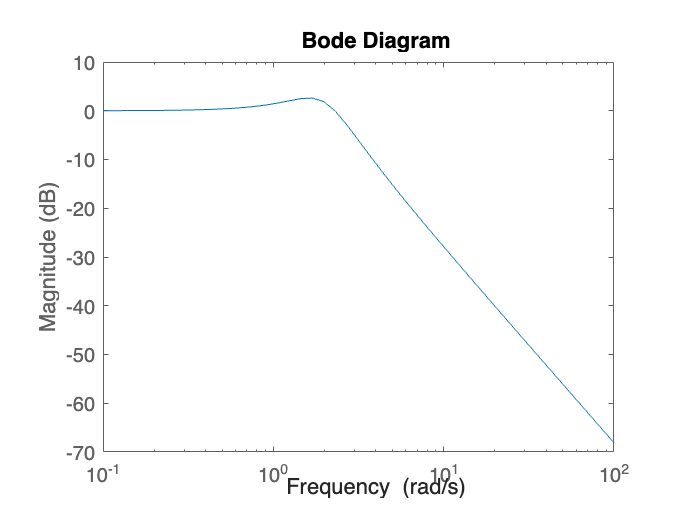

Mb = 1/sqrt(2);


figure, hold on


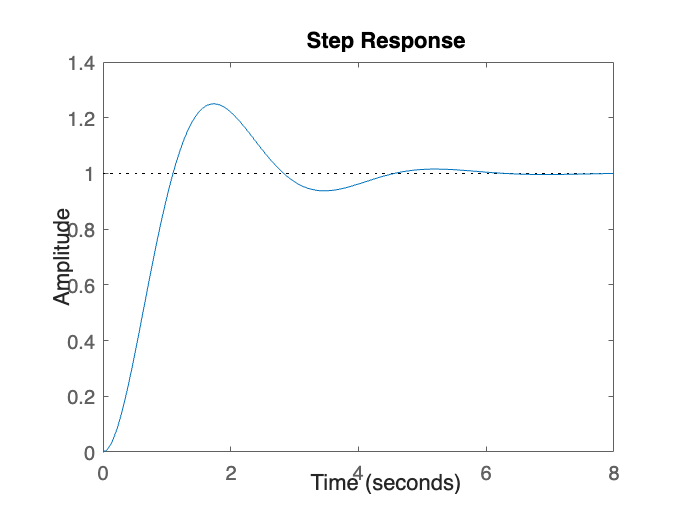

M = [Ma Mb];
for k = 1:2

    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

zeta = 0.6901

wn = 0.5796

M =
 
         0.336
  -------------------
  s^2 + 0.8 s + 0.336
 
Continuous-time transfer function.
Model Properties


Ma =
 
         0.34
  ------------------
  s^2 + 0.8 s + 0.34
 
Continuous-time transfer function.
Model Properties


Mb =
 
             0.2414
  -----------------------------
  s^3 + 2.5 s^2 + 1.84 s + 0.34
 
Continuous-time transfer function.
Model Properties


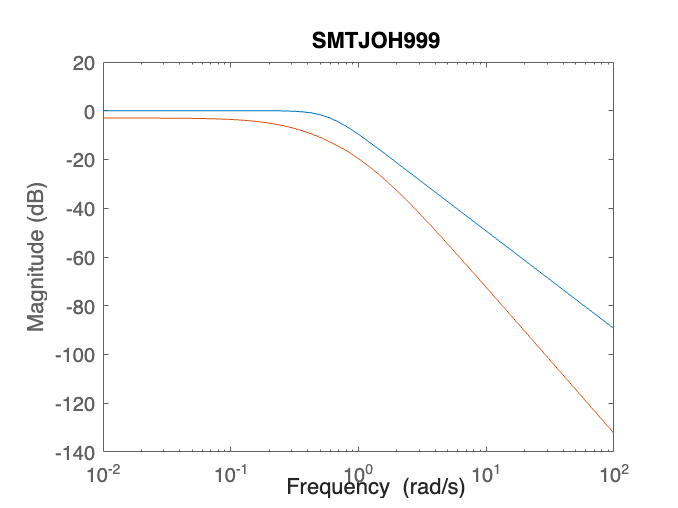


    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )

        Lw = squeeze( freqresp(L,w0) );

        plot(angle(Lw)*180/pi,20*log10(abs(Lw)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
nichols(L)
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')

Using the desired $M_A$, $M_B$, and $\omega_0$ values shows that $L(s)$ does adhere to the design constraints, which means that we have potentially met the original time-domain specifications of a settling time of 5 seconds and percentage overshoot of $25$%. We can verify this using a step response, as generated from the code below.

T = feedback(L,1);
figure, hold on
step(T,6)
yline(1.25,'--b','$\% OS=25\%$','Interpreter','latex')
xline(5,'--r','$t_s=5$s','Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1.4])

The step response shows that both the settling time and overshoot specifications have been met. 

It is easy to show that if we instead considered $L(s)=\frac{10}{s(s+2)$, then we would not meet the design constraints in the log-polar plane, as well as the original time-domain constraints. A comparison of $L_1(s)=\frac{5}{s(s+2)}$ and $L_2(s)=\frac{10}{s(s+2)}=2L_1(s)$ is shown using the code below.

clear
s = tf('s');

L1 = 5/s/(s+2);

w0 = 1.1222

L2 = 10/s/(s+2);

w0 = 1.13; %closed-loop bandwidth frequency
Ma = 1.35; %overbound

zeta = 0.4037

Mb = 1/sqrt(2);

wn = 1.9816

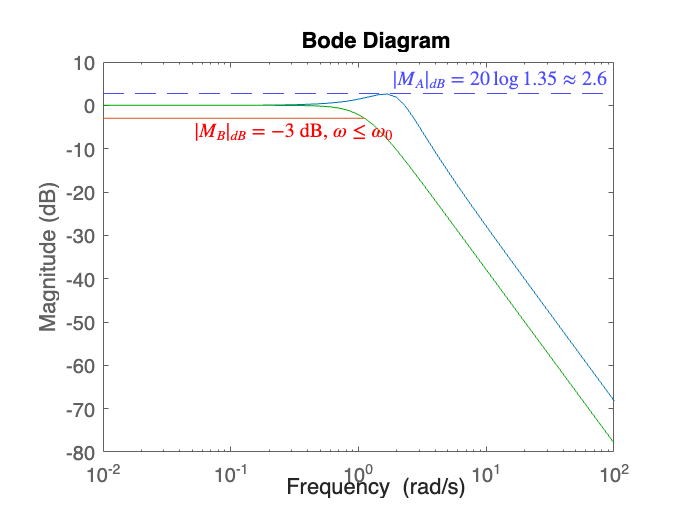



figure, hold on

M = [Ma Mb];
for k = 1:2
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);


    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)

zeta = 0.5912

wn = 0.6766

Ma = 1.0487

        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )

w0 = 0.5611

        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw1 = squeeze( freqresp(L1,w0) );
        Lw2 = squeeze( freqresp(L2,w0) );

        plot(angle(Lw1)*180/pi,20*log10(abs(Lw1)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
        plot(angle(Lw2)*180/pi,20*log10(abs(Lw2)),'go',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end
nichols(L1),nichols(L2)
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$','Interpreter','latex')
%
T1 = feedback(L1,1);
T2 = feedback(L2,1);
figure, hold on
step(T1,6),step(T2,6)
yline(1.25,'--b','$\% OS=25\%$','Interpreter','latex')
xline(5,'--r','$t_s=5$s','Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1.4])

As shown in the log-polar plot and step response, $L_2(s)$ violates the percentage overshoot boundary. 

####  Question 11: Determine the value(s) of $K$ for which $L(s)=\frac{5K}{s(s+2)$*, when placed in a unity-feedback loop, will no longer satisfy the closed-loop second-order specifications of a settling time of 5 seconds, percentage overshoot of *$25$*%, zero steady-state error for reference step inputs.*

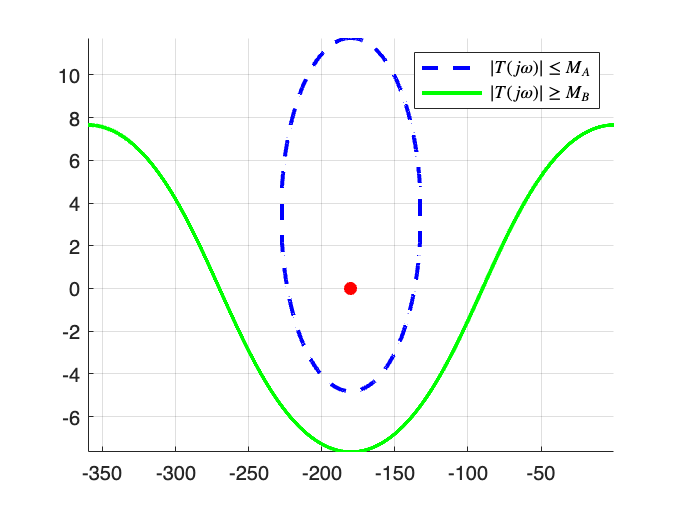

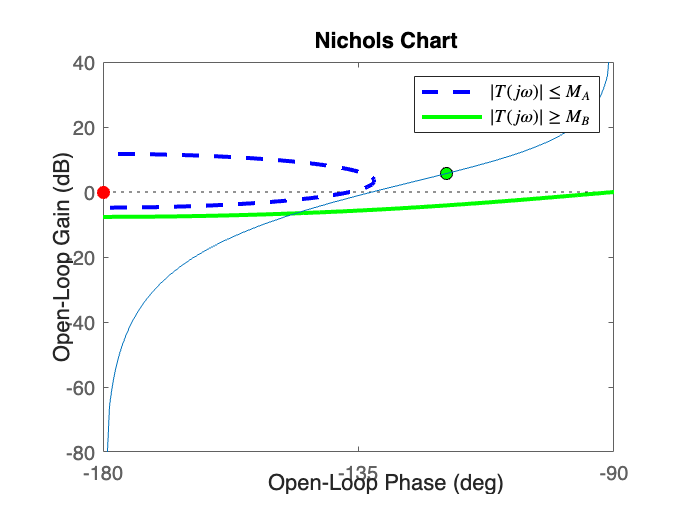

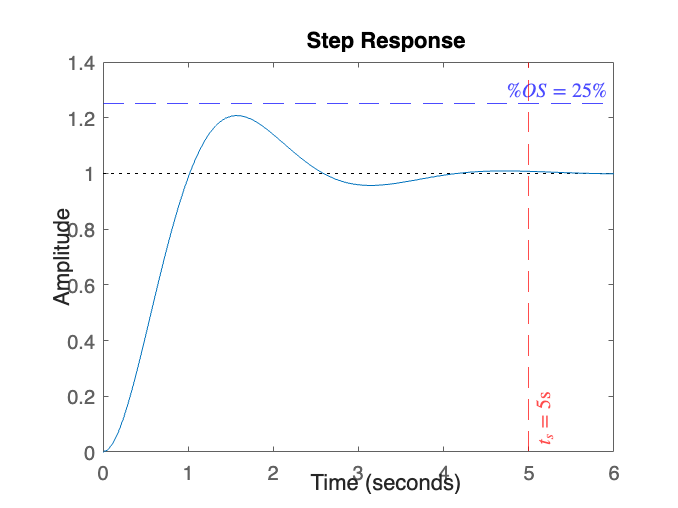

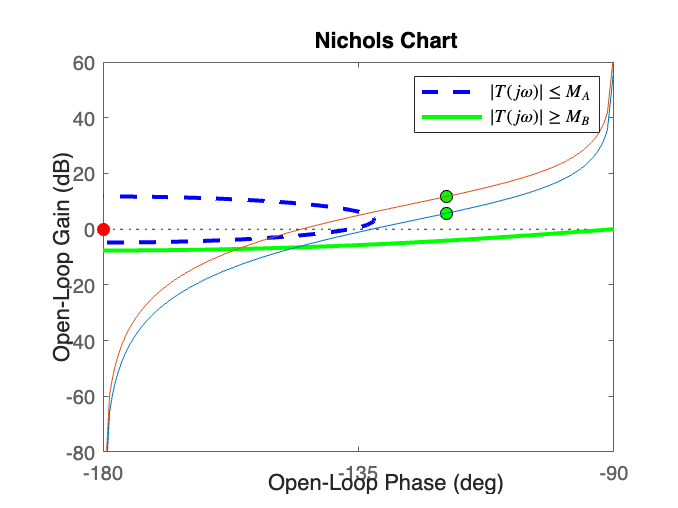

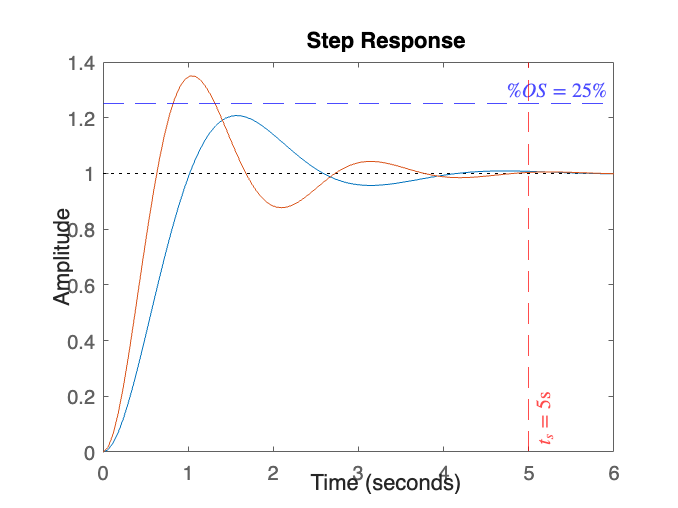

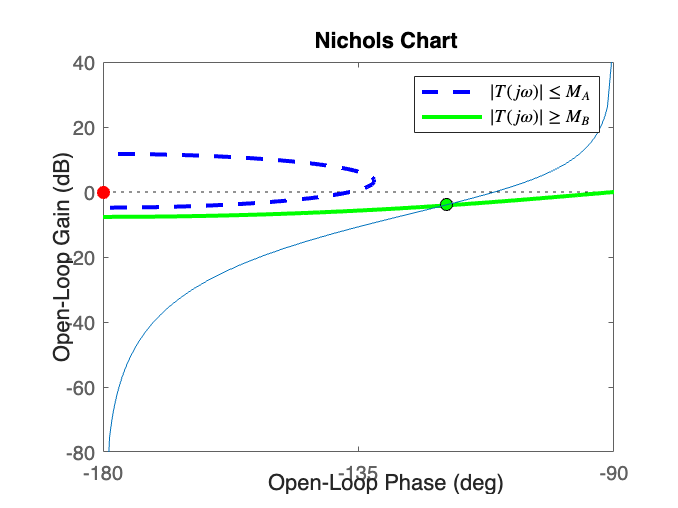

%Code block (if required)


***This concludes Virtual Lab 8.***